# Transfer Learning for Fastener Detection 

In this script, you'll walk through the steps of training a detection model for the fasteners dataset. Here, we'll use the YOLOv4 object detector with two detection heads, or "tiny-yolo." This approach was chosen so that you have another example of estimating and using anchor boxes. If you use YOLOX, then you can skip those steps.

**You do not need to run this script.** The trained model is provided for you. For reference, the training took approximately 2 hours on a GPU. Training on a CPU may take multiple times longer. 

## Import ground truth data object  and convert to datastores

load fastenerTrainGT.mat fastenerTrainGT

Convert ground truth data to an `imageDatastore` and `boxLabelDatastore` 

[imds,blds] = objectDetectorTrainingData(fastenerTrainGT);
nFiles = length(imds.Files)
classes = categories(blds.LabelData{1,2})

Combine the `imageDatastore` and `boxLabelDatastore` datastores

data = combine(imds,blds);

## Resize the data 

To perform preprocessing on object detection data data in a combined datastore, you need to use the `transform` function with a custom data alteration function that you provide. See the [documentation](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.transform.html#mw_43aab448-b9fd-4306-b006-6910e8420fdc) for reference on the syntax. 

Here, you want to reduce the data size to `targetDataSize` defined below. To do this, use the `resizeDetectionData` function which we provided in your course files so that you can re-use it in your own applications. 

targetDataSize = [320 480 3]; 
data = transform(data, @(dataIn) resizeDetectionData(dataIn,targetDataSize)); 

## Estimate anchor boxes

Since you will be using YOLO v4 which requires anchor boxes, you need to estimate them based on the resized data. As you saw in the previous video, the workflow is to evaluate different numbers of anchor boxes using the intersection over union (IoU) of the anchor boxes with the ground truth as the evaluation metric. The first step is to choose a maximum number of anchors to evaluate. Here, we start with 24: 

maxAnchors = 24; 

Then, initialize variables to store results for all iterations. Here, mean IoU will be a scalar at each iteration, so use a vector of zeros. Each set of anchor boxes will be a matrix, so store each iteration in an element of a cell array. 

meanIoU = zeros(maxAnchors, 1);
anchorBoxes = cell(maxAnchors, 1);

Estimate the anchor boxes and mean IoU over a range of 1 to `maxAnchors`.

for idx = 1:maxAnchors
    [anchorBoxes{idx}, meanIoU(idx)] = estimateAnchorBoxes(data, idx);
end

**Visualize the results**

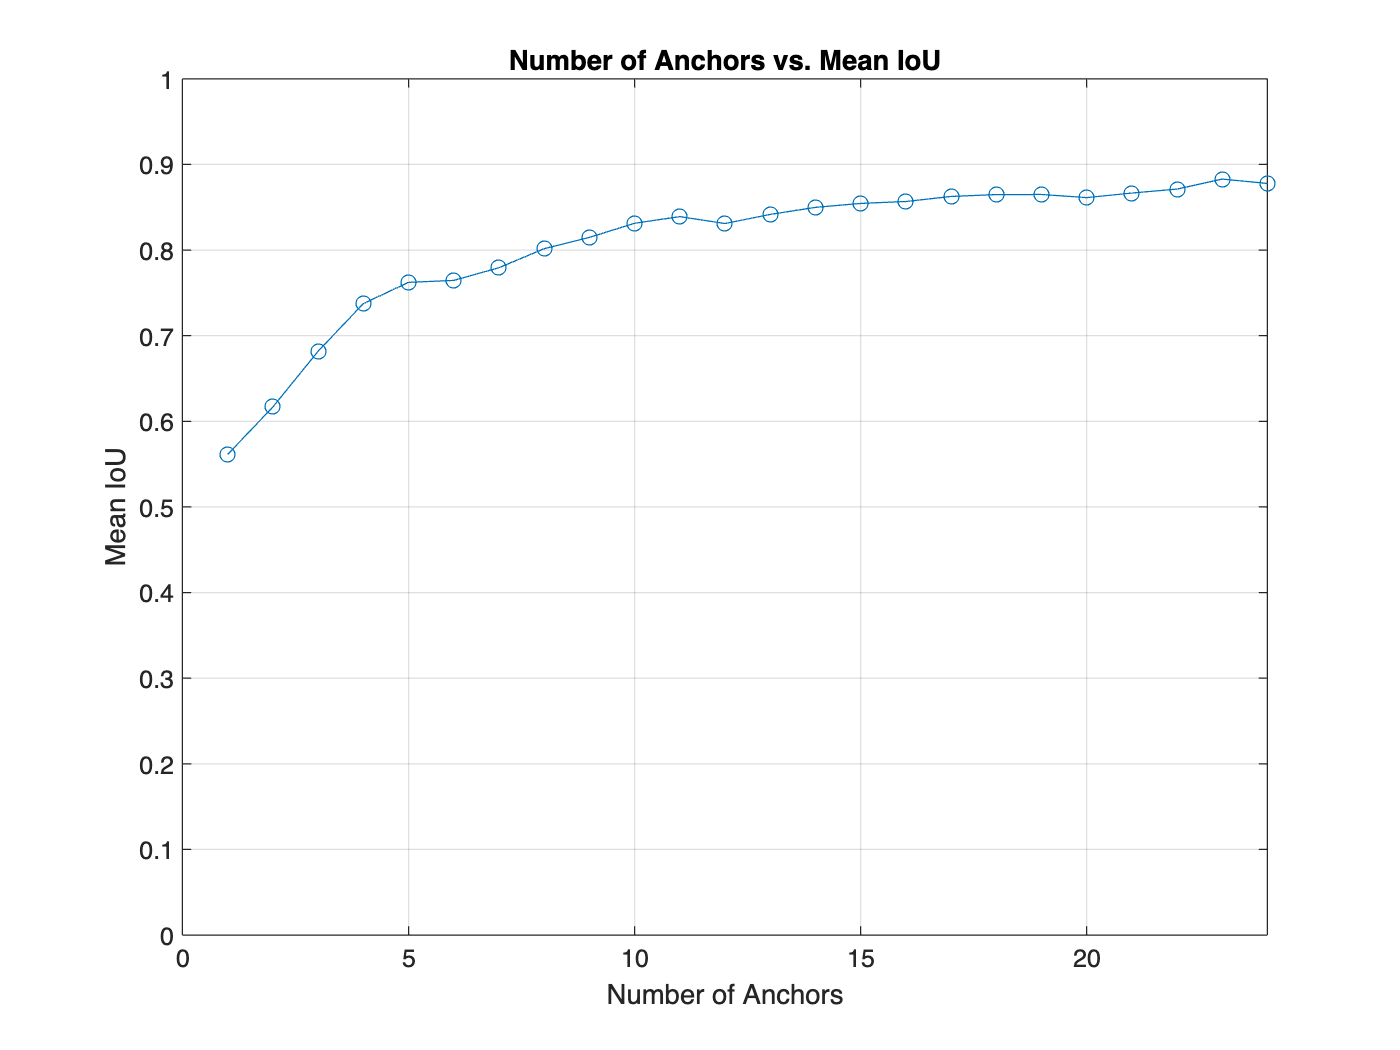

plot(1:maxAnchors, meanIoU, "-o")
axis([0,maxAnchors,0,1])
grid
xlabel("Number of Anchors")
ylabel("Mean IoU")
title("Number of Anchors vs. Mean IoU")

## Split the data into training and validation sets

Shuffle the datastore to randomize the files before making the training validation split.

data = shuffle(data);

Next, select a fraction of files to use for training and calculate the number of training files. Here, we keep 80% of the training data as training and use 20% for validation. 

trainingFraction = 0.8;
numTraining = floor(nFiles*trainingFraction);

Finally, use the `subset` function to split the data into training and validation sets.

trainingData = subset(data, 1:numTraining);
validationData = subset(data, (numTraining+1):nFiles);

## Build a detector 

Now build a detector to train. In this case, a YOLOv4 object detector. Based on the analysis above, it looks like 12 anchor boxes is a good initial number to try. 

anchors = anchorBoxes{12};

Sort the anchor boxes by area and assign them to the detection heads appropriately based their source depth in the backbone network. To do this, calculate the area of the anchors and then sort them by size. 

anchorArea = anchors(:,1).*anchors(:,2);
[~, idx] = sort(anchorArea);
anchors = anchors(idx, :);

In this example, there are two detection heads for the tiny-yolo network. 

trainingAnchors = cell(2, 1);
trainingAnchors{1} = anchors(1:6,:);
trainingAnchors{2} = anchors(7:12,:);

Now build the detector object. 

- The first input here specifies the name of the pre-trained network, in this case the "tiny" backbone (small version of Darknet 53). 

- The second input is the class names obtained earlier from the `boxLabelDatastore`.

- The third input is the sorted anchor boxes. 

- Finally, specify the `InputSize` and `targetDataSize` name-value pair. This lets the network know what size data to use for training and inference. 

detector = yolov4ObjectDetector("tiny-yolov4-coco",classes,trainingAnchors,"InputSize",targetDataSize);

## Setup training options and train the detector

Now, set the [training options](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html#namevaluepairarguments) for the optimization algorithm to use. Below, we provide a set of options which work decently well for this application. You'll need to use your insights into the application, data, and almost certainly some trial and error to find the best set of training options for your own work. See the video [Common Training Options](https://www.coursera.org/learn/introduction-deep-learning-computer-vision/lecture/fJQ00/common-training-options) from course one of this specialization for more information.

options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="none",...
    MiniBatchSize=64,...
    L2Regularization=0.001,... 
    MaxEpochs=300,... 
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=true,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=10,...
    Plots = "training-progress",...
    ValidationData=validationData,...
    ValidationFrequency=5,...
    OutputNetwork="best-validation-loss");

The line below is commented since the training can take quite a while depending on the computational resources available to you. (It took us a couple hours using a machine with a GPU.) If you want to give it a try, uncomment below and run the script. 

% [detector,info] = trainYOLOv4ObjectDetector(trainingData,detector,options);

## Save results

Remember, the model that gets trained as we set this script up is already provided with the course files. If you make changes and want to save your results, make sure to save your model using a different filename.

*Copyright 2024 The MathWorks, Inc.*